clc
clear all
syms R xtheta rtheta r0 b wtheta
format default
wh = 12

wh = 12

wtheta = 30

wtheta = 30

b = 40

b = 40

R = wh./wtheta

R = 0.4000

rtheta = 0.45.*b.^2

rtheta = 720

xbar = 0.09

xbar = 0.0900

xtheta = 0.09.*b

xtheta = 3.6000

bxtheta = b.*xtheta

bxtheta = 144

Bxtheta = linspace(-1,1,100).*b

Bxtheta =   -40.0000  -39.1919  -38.3838  -37.5758  -36.7677  -35.9596  -35.1515  -34.3434  -33.5354  -32.7273  -31.9192  -31.1111  -30.3030  -29.4949  -28.6869  -27.8788  -27.0707  -26.2626  -25.4545  -24.6465  -23.8384  -23.0303  -22.2222  -21.4141  -20.6061  -19.7980  -18.9899  -18.1818  -17.3737  -16.5657  -15.7576  -14.9495  -14.1414  -13.3333  -12.5253  -11.7172  -10.9091  -10.1010   -9.2929   -8.4848   -7.6768   -6.8687   -6.0606   -5.2525   -4.4444   -3.6364   -2.8283   -2.0202   -1.2121   -0.4040


r0 = (rtheta.^2- bxtheta.^2).^0.5

r0 = 705.4530

Ro = (rtheta.^2- Bxtheta.^2).^0.5

Ro =   718.8880  718.9325  718.9761  719.0188  719.0606  719.1015  719.1414  719.1805  719.2186  719.2558  719.2921  719.3275  719.3620  719.3956  719.4283  719.4601  719.4909  719.5209  719.5499  719.5780  719.6053  719.6316  719.6570  719.6815  719.7051  719.7278  719.7495  719.7704  719.7904  719.8094  719.8275  719.8448  719.8611  719.8765  719.8910  719.9047  719.9174  719.9291  719.9400  719.9500  719.9591  719.9672  719.9745  719.9808  719.9863  719.9908  719.9944  719.9972  719.9990  719.9999


omegasq1 = (1 + R^2 + sqrt((1-R^2)^2+4*R^2*(bxtheta/rtheta)^2)) /(2*(r0/rtheta)^2)

omegasq1 = 1.0495

omegasq2 = (1 + R^2 - sqrt((1-R^2)^2+4*R^2*(bxtheta/rtheta)^2)) /(2*(r0/rtheta)^2)

omegasq2 = 0.1588

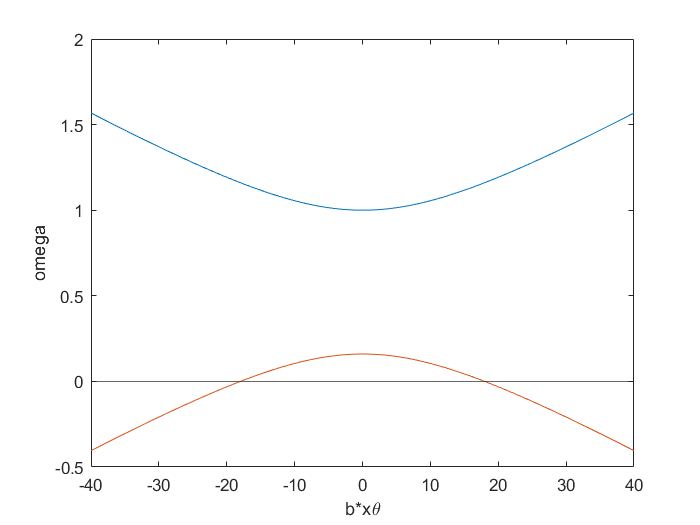

for i= 1:length(Bxtheta)
Omega1(i) = ((1 + R.^2) - (sqrt((1 - (R.^2)).^2 + 4.*(R^2).*(Bxtheta(i).*b ./rtheta).^2)))./(2.*(Ro(i)./rtheta).^2);
Omega2(i) = ((1 + R.^2) + (sqrt((1 - (R.^2)).^2 + 4.*(R^2).*(Bxtheta(i).*b ./rtheta).^2)))./(2.*(Ro(i)./rtheta).^2);
end
plot(Bxtheta,Omega2)
hold on
plot(Bxtheta,Omega1)
yline(0)
xlabel('b*x\theta')
ylabel('omega')
hold off

omega1 = sqrt(omegasq1)

omega1 = 1.0245

omega2 = sqrt(omegasq2)

omega2 = 0.3985

A = [omega1.^2 + R.^2, -omega1.^2 .*xtheta; -omega1.^2 .*xtheta, (-omega1.^2 + 1).*rtheta.^2]

A = 	1.0e+04 *

    0.0001   -0.0004
   -0.0004   -2.5678


B = [omega2.^2 + R.^2, -omega2.^2 .*xtheta; -omega2.^2 .*xtheta, (-omega2.^2 + 1).*rtheta.^2]

B = 	1.0e+05 *

    0.0000   -0.0000
   -0.0000    4.3608


phi1 = (omega1^2+R^2-omega1^2*bxtheta)/ (omega1^2*bxtheta - ((-omega1^2+1)*rtheta^2))

phi1 = -0.0058

phi_ratio1 = omega1^2*xbar/(R^2-omega1^2)

phi_ratio1 = -0.1062

phi_ratio2 = omega2^2*xbar/(R^2-omega2^2)

phi_ratio2 = 11.9187

ubar_12 = 1/phi_ratio2

ubar_12 = 0.0839

Phi1 = [1;ubar_12]

Phi1 =     1.0000
    0.0839


Phi2 = [phi_ratio1;1]

Phi2 =    -0.1062
    1.0000


rtheta_b = 0.45

rtheta_b = 0.4500

Cl = 6.5

Cl = 6.5000

mu = 15

mu = 15

a = 0.2

a = 0.2000

bxa = (b - 0.25.*(2*b))

bxa = 20

eb = (bxa + b*(a))./(b)

eb = 0.7000

db = eb + xbar

db = 0.7900

Vb = linspace(0,2.5,100)

Vb =          0    0.0253    0.0505    0.0758    0.1010    0.1263    0.1515    0.1768    0.2020    0.2273    0.2525    0.2778    0.3030    0.3283    0.3535    0.3788    0.4040    0.4293    0.4545    0.4798    0.5051    0.5303    0.5556    0.5808    0.6061    0.6313    0.6566    0.6818    0.7071    0.7323    0.7576    0.7828    0.8081    0.8333    0.8586    0.8838    0.9091    0.9343    0.9596    0.9848    1.0101    1.0354    1.0606    1.0859    1.1111    1.1364    1.1616    1.1869    1.2121    1.2374


A = rtheta_b.^2 - xbar.^2

A = 0.1944

B = rtheta_b.^2.*(1+R.^2) - ((db.*Cl)./(pi.*mu)).*Vb.^2

B =     0.2349    0.2348    0.2346    0.2343    0.2338    0.2332    0.2324    0.2315    0.2305    0.2293    0.2280    0.2265    0.2249    0.2232    0.2213    0.2193    0.2171    0.2148    0.2124    0.2098    0.2071    0.2043    0.2013    0.1981    0.1949    0.1915    0.1879    0.1842    0.1804    0.1765    0.1724    0.1681    0.1637    0.1592    0.1546    0.1498    0.1448    0.1398    0.1346    0.1292    0.1237    0.1181    0.1123    0.1064    0.1004    0.0942    0.0879    0.0814    0.0748    0.0681


C = rtheta_b.^2.*R.^2 - ((R.^2.*Cl.*eb)./(mu.*pi))*Vb.^2

C =     0.0324    0.0324    0.0324    0.0323    0.0322    0.0322    0.0320    0.0319    0.0318    0.0316    0.0314    0.0312    0.0310    0.0307    0.0305    0.0302    0.0299    0.0296    0.0292    0.0288    0.0285    0.0281    0.0276    0.0272    0.0267    0.0262    0.0257    0.0252    0.0247    0.0241    0.0235    0.0229    0.0223    0.0217    0.0210    0.0203    0.0196    0.0189    0.0182    0.0174    0.0166    0.0158    0.0150    0.0142    0.0133    0.0125    0.0116    0.0106    0.0097    0.0087


O1 = (B + sqrt((B.^2) - (4.*A.*C)))./(2.*A)

O1 =    1.0495 + 0.0000i   1.0492 + 0.0000i   1.0481 + 0.0000i   1.0463 + 0.0000i   1.0437 + 0.0000i   1.0404 + 0.0000i   1.0364 + 0.0000i   1.0317 + 0.0000i   1.0262 + 0.0000i   1.0200 + 0.0000i   1.0131 + 0.0000i   1.0054 + 0.0000i   0.9970 + 0.0000i   0.9879 + 0.0000i   0.9780 + 0.0000i   0.9674 + 0.0000i   0.9561 + 0.0000i   0.9440 + 0.0000i   0.9312 + 0.0000i   0.9176 + 0.0000i   0.9033 + 0.0000i   0.8882 + 0.0000i   0.8724 + 0.0000i   0.8558 + 0.0000i   0.8385 + 0.0000i   0.8204 + 0.0000i   0.8015 + 0.0000i   0.7818 + 0.0000i   0.7614 + 0.0000i   0.7401 + 0.0000i   0.7180 + 0.0000i   0.6951 + 0.0000i   0.6713 + 0.0000i   0.6467 + 0.0000i   0.6211 + 0.0000i   0.5945 + 0.0000i   0.5670 + 0.0000i   0.5382 + 0.0000i   0.5082 + 0.0000i   0.4767 + 0.0000i   0.4434 + 0.0000i   0.4075 + 0.0000i   0.3676 + 0.0000i   0.3178 + 0.0000i   0.2582 + 0.0437i   0.2423 + 0.0732i   0.2260 + 0.0915i   0.2094 + 0.1044i   0.1924 + 0.1136i   0.1751 + 0.1198i


O2 = (B - sqrt((B.^2) - (4.*A.*C)))./(2.*A)

O2 =    0.1588 + 0.0000i   0.1588 + 0.0000i   0.1588 + 0.0000i   0.1589 + 0.0000i   0.1589 + 0.0000i   0.1590 + 0.0000i   0.1591 + 0.0000i   0.1591 + 0.0000i   0.1592 + 0.0000i   0.1594 + 0.0000i   0.1595 + 0.0000i   0.1597 + 0.0000i   0.1598 + 0.0000i   0.1600 + 0.0000i   0.1603 + 0.0000i   0.1605 + 0.0000i   0.1608 + 0.0000i   0.1610 + 0.0000i   0.1614 + 0.0000i   0.1617 + 0.0000i   0.1621 + 0.0000i   0.1625 + 0.0000i   0.1629 + 0.0000i   0.1634 + 0.0000i   0.1640 + 0.0000i   0.1646 + 0.0000i   0.1652 + 0.0000i   0.1659 + 0.0000i   0.1667 + 0.0000i   0.1676 + 0.0000i   0.1686 + 0.0000i   0.1697 + 0.0000i   0.1710 + 0.0000i   0.1724 + 0.0000i   0.1740 + 0.0000i   0.1759 + 0.0000i   0.1781 + 0.0000i   0.1808 + 0.0000i   0.1840 + 0.0000i   0.1879 + 0.0000i   0.1930 + 0.0000i   0.1999 + 0.0000i   0.2102 + 0.0000i   0.2296 + 0.0000i   0.2582 - 0.0437i   0.2423 - 0.0732i   0.2260 - 0.0915i   0.2094 - 0.1044i   0.1924 - 0.1136i   0.1751 - 0.1198i


B1 = rtheta_b.^2.*(1+R.^2) - ((db.*Cl)./(pi.*mu)).*Vb.^2

B1 =     0.2349    0.2348    0.2346    0.2343    0.2338    0.2332    0.2324    0.2315    0.2305    0.2293    0.2280    0.2265    0.2249    0.2232    0.2213    0.2193    0.2171    0.2148    0.2124    0.2098    0.2071    0.2043    0.2013    0.1981    0.1949    0.1915    0.1879    0.1842    0.1804    0.1765    0.1724    0.1681    0.1637    0.1592    0.1546    0.1498    0.1448    0.1398    0.1346    0.1292    0.1237    0.1181    0.1123    0.1064    0.1004    0.0942    0.0879    0.0814    0.0748    0.0681


C1 = rtheta_b.^2.*R.^2 - ((R.^2.*Cl.*eb)./(mu.*pi)).*Vb.^2

C1 =     0.0324    0.0324    0.0324    0.0323    0.0322    0.0322    0.0320    0.0319    0.0318    0.0316    0.0314    0.0312    0.0310    0.0307    0.0305    0.0302    0.0299    0.0296    0.0292    0.0288    0.0285    0.0281    0.0276    0.0272    0.0267    0.0262    0.0257    0.0252    0.0247    0.0241    0.0235    0.0229    0.0223    0.0217    0.0210    0.0203    0.0196    0.0189    0.0182    0.0174    0.0166    0.0158    0.0150    0.0142    0.0133    0.0125    0.0116    0.0106    0.0097    0.0087


O11 = (B1 + sqrt((B1.^2) - (4.*A.*C1)))./(2.*A)

O11 =    1.0495 + 0.0000i   1.0492 + 0.0000i   1.0481 + 0.0000i   1.0463 + 0.0000i   1.0437 + 0.0000i   1.0404 + 0.0000i   1.0364 + 0.0000i   1.0317 + 0.0000i   1.0262 + 0.0000i   1.0200 + 0.0000i   1.0131 + 0.0000i   1.0054 + 0.0000i   0.9970 + 0.0000i   0.9879 + 0.0000i   0.9780 + 0.0000i   0.9674 + 0.0000i   0.9561 + 0.0000i   0.9440 + 0.0000i   0.9312 + 0.0000i   0.9176 + 0.0000i   0.9033 + 0.0000i   0.8882 + 0.0000i   0.8724 + 0.0000i   0.8558 + 0.0000i   0.8385 + 0.0000i   0.8204 + 0.0000i   0.8015 + 0.0000i   0.7818 + 0.0000i   0.7614 + 0.0000i   0.7401 + 0.0000i   0.7180 + 0.0000i   0.6951 + 0.0000i   0.6713 + 0.0000i   0.6467 + 0.0000i   0.6211 + 0.0000i   0.5945 + 0.0000i   0.5670 + 0.0000i   0.5382 + 0.0000i   0.5082 + 0.0000i   0.4767 + 0.0000i   0.4434 + 0.0000i   0.4075 + 0.0000i   0.3676 + 0.0000i   0.3178 + 0.0000i   0.2582 + 0.0437i   0.2423 + 0.0732i   0.2260 + 0.0915i   0.2094 + 0.1044i   0.1924 + 0.1136i   0.1751 + 0.1198i


O22 = (B1 - sqrt((B1.^2) - (4.*A.*C1)))./(2.*A)

O22 =    0.1588 + 0.0000i   0.1588 + 0.0000i   0.1588 + 0.0000i   0.1589 + 0.0000i   0.1589 + 0.0000i   0.1590 + 0.0000i   0.1591 + 0.0000i   0.1591 + 0.0000i   0.1592 + 0.0000i   0.1594 + 0.0000i   0.1595 + 0.0000i   0.1597 + 0.0000i   0.1598 + 0.0000i   0.1600 + 0.0000i   0.1603 + 0.0000i   0.1605 + 0.0000i   0.1608 + 0.0000i   0.1610 + 0.0000i   0.1614 + 0.0000i   0.1617 + 0.0000i   0.1621 + 0.0000i   0.1625 + 0.0000i   0.1629 + 0.0000i   0.1634 + 0.0000i   0.1640 + 0.0000i   0.1646 + 0.0000i   0.1652 + 0.0000i   0.1659 + 0.0000i   0.1667 + 0.0000i   0.1676 + 0.0000i   0.1686 + 0.0000i   0.1697 + 0.0000i   0.1710 + 0.0000i   0.1724 + 0.0000i   0.1740 + 0.0000i   0.1759 + 0.0000i   0.1781 + 0.0000i   0.1808 + 0.0000i   0.1840 + 0.0000i   0.1879 + 0.0000i   0.1930 + 0.0000i   0.1999 + 0.0000i   0.2102 + 0.0000i   0.2296 + 0.0000i   0.2582 - 0.0437i   0.2423 - 0.0732i   0.2260 - 0.0915i   0.2094 - 0.1044i   0.1924 - 0.1136i   0.1751 - 0.1198i


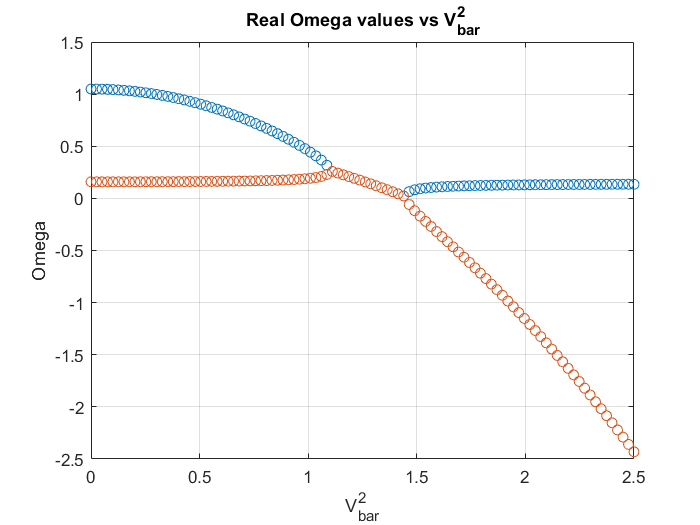

plot(Vb, real(O1), 'o')
hold on
plot (Vb,real(O2), 'o')
grid on
hold off
ylabel ("Omega")
xlabel ("V_{bar}^2") 
title ('Real Omega values vs V_{bar}^2')

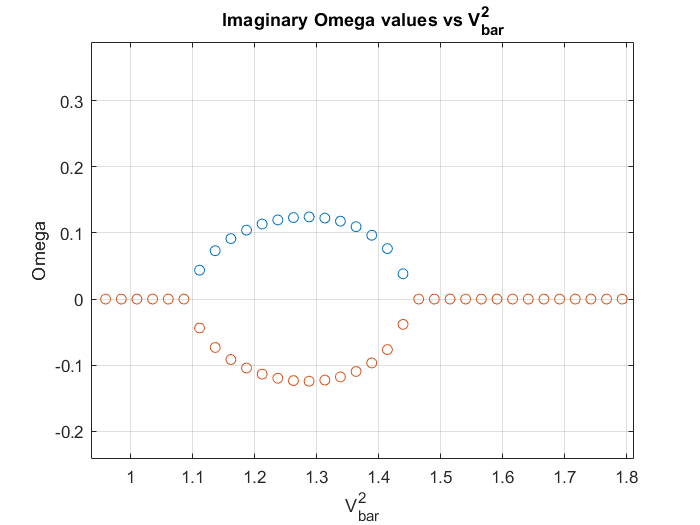

plot(Vb, imag(O11),'o')
hold on
plot (Vb,imag(O22), 'o')
grid on
hold off
xlim([0.936 1.812])
ylim([-0.242 0.389])
ylabel ("Omega")
xlabel ("V_{bar}^2") 
title ('Imaginary Omega values vs V_{bar}^2')

D2 = B1.^2 - 4.*A.*C1

D2 =     0.0300    0.0300    0.0299    0.0298    0.0296    0.0294    0.0291    0.0288    0.0284    0.0280    0.0275    0.0270    0.0265    0.0259    0.0253    0.0246    0.0239    0.0232    0.0224    0.0216    0.0208    0.0199    0.0190    0.0181    0.0172    0.0163    0.0153    0.0143    0.0134    0.0124    0.0114    0.0104    0.0095    0.0085    0.0076    0.0066    0.0057    0.0048    0.0040    0.0032    0.0024    0.0016    0.0009    0.0003   -0.0003   -0.0008   -0.0013   -0.0016   -0.0019   -0.0022


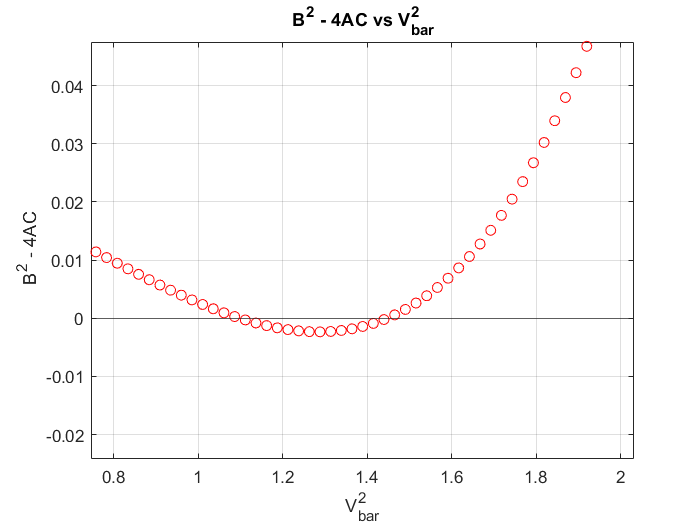

plot(Vb,real(D2), 'ro')
grid on
yline(0)
xlim([0.746 2.031])
ylim([-0.0242 0.0475])
ylabel (" B^2 - 4AC")
xlabel ("V_{bar}^2") 
title ('B^2 - 4AC vs V_{bar}^2')